# IEEE European Test Feeder

Copyright © 2026, The MathWorks, Inc.

## Introduction

This script builds the IEEE European Test Feeder in Simscape Electrical using subsystem reference. The model is EMT and contains quasi-static constant PQ loads. These loads are single-phase, but to avoid a PLL the loads have been implemented as three-phase equivalent, by creating -120 degree and +120 degree phase shifted versions of the single-phase voltage in order to take advantage of Clarke and Park implementation. This implementation, while computationally more expensive, allows clean reference signals within 2/3 of a cycle to be created. This approach is valid for quasi-static EMT simulations with fixed frequency.

The published benchmark contains results for a 24-hr period at one minute intervals : 1,440 operational points in total. In order to compare the EMT model against these results, we change operational point every two cycles and measure RMS of the EMT waveforms. Total simulation time for the EMT model is 2/50*1440 = 57.6s.

bdclose all
clear

## Network data

Before running this script, you must download the network data.

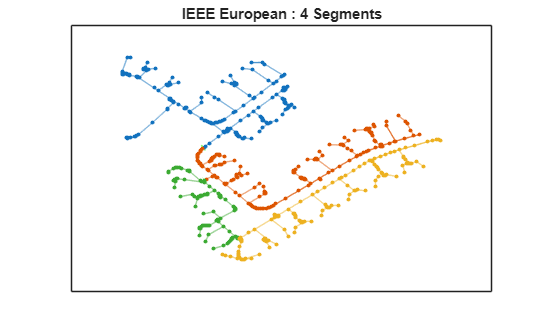

European_LV_graph_4segments


Ts = 5e-5; %#ok<*NASGU>

buses1 = dataEuropean.buses.Bus_No;

idxLoad = ismember(dataEuropean.loads.Bus_No,buses1);
data.loads = dataEuropean.loads(idxLoad,:);

idxLines = ismember(dataEuropean.lines.From,buses1) & ismember(dataEuropean.lines.To,buses1);
data.lines = dataEuropean.lines(idxLines,:);

idxBuses = ismember(dataEuropean.buses.Bus_No,buses1);
data.buses = dataEuropean.buses(idxBuses,:);

data.buses.X_Coord = 3*data.buses.X_Coord - 3*data.buses.X_Coord(1);
data.buses.Y_Coord = 3*data.buses.Y_Coord - 3*data.buses.Y_Coord(1);

data.lineCodes = dataEuropean.lineCodes;

data.source_bus = dataEuropean.source_bus;

nl = numel(data.lines.From);

for xa = 1:nl

    f_t = [data.lines.From(xa) data.lines.To(xa)];

    idxLC = ismember(data.lineCodes.Name,data.lines.LineCode(xa));

    R1 = data.lineCodes.R1(idxLC)*data.lines.Length(xa)/1000;
    R0 = data.lineCodes.R0(idxLC)*data.lines.Length(xa)/1000;
    L1 = data.lineCodes.X1(idxLC)*data.lines.Length(xa)/2/pi/50/1000;
    L0 = data.lineCodes.X0(idxLC)*data.lines.Length(xa)/2/pi/50/1000;

    RS = (2*R1 + R0)/3;
    LS = (2*L1 + L0)/3;
    
    RM = (R0 - R1)/3;
    LM = (L0 - L1)/3;

    eval(['lineData.R_',num2str(f_t(1)),'_',num2str(f_t(2)),' = [RS RM RM;RM RS RM;RM RM RS];']);
    eval(['lineData.L_',num2str(f_t(1)),'_',num2str(f_t(2)),' = [LS LM LM;LM LS LM;LM LM LS];']);
   
end

data1 = data;

## Build network segments as model references

nv  = [{'n1'},{'n2'},{'n3'},{'n4'}];
nlc  = [{'n1_lineConns'},{'n2_lineConns'},{'n3_lineConns'},{'n4_lineConns'}];

for x = 1:4

nn  = eval(nv{x});

buses1 = data1.buses.Bus_No(nn,1);

idxLines = ismember(data1.lines.From,buses1) & ismember(data1.lines.To,buses1);
data.lines = data1.lines(idxLines,:);

idxBuses = ismember(data1.buses.Bus_No,buses1);
data.buses = data1.buses(idxBuses,:);

## model name

mdl = 'blank_canvas_curr_SR';

open(mdl)

## add buses

bus_placement_ssc_EMT_curr(mdl,data)

## add lines

line_placement_ssc_European(mdl,data)

## add source

if x == 1

    source_placement_ssc(mdl,data)

end

## data saving

define_outputs_curr(mdl)

## inputs

clear tagI
tagI = define_inputs_curr(mdl);
eval([nv{x},'_tagI = tagI;'])

## connect solver configuration and configure

% find the first bus

hba = find_system(mdl,'FindAll','on','RegExp','on','Name','Bus');
bus_name = get(hba(1),'Name');

hb = find_system(mdl,'FindAll','on','Name',bus_name);

% copy solver configuration over to model
hsc = add_block('nesl_utility/Solver Configuration',[mdl,'/Solver Configuration']);

% put solver configuration near bus 1
psc = get(hsc,'Position');
pos = psc - [psc(1) psc(2) psc(1) psc(2)];
pb = get(hb,'Position');
set(hsc,'Position',pos + [pb(1)-150 pb(2)-50 pb(1)-150 pb(2)-50])

% get port handles
b1 = get(hb,'Porthandles');
b2 = get(hsc,'Porthandles');

% connect the solver configuration to the bus
add_line(mdl,b1.LConn(1),b2.RConn(1))

% configure the solver parameters for large-scale simulation
set(hsc,'IndexReductionMethod','None')
set(hsc,'ConsistencyTolSource','LOCAL')
set(hsc,'ConsistencyAbsTol','1e4')
set(hsc,'ConsistencyRelTol','1e4')
set(hsc,'ConsistencyTolFactor','1')
set(hsc,'UseLocalSolver','on')
set(hsc,'DoFixedCost','on')
set(hsc,'MaxNonlinIter','1')
set(hsc,'ResolveIndetEquations','off')
set(hsc,'LocalSolverChoice','NE_BACKWARD_EULER_ADVANCER')
set(hsc,'LocalSolverSampleTime','Ts')
set(hsc,'LinearAlgebra','Sparse')
set(hsc,'AutomaticFiltering','off')

## signal buses


clear slB*

mdl1 = 'busCreators01curr';

open_system(mdl1)

% delete the existing blocks
try
    delete_block([mdl1,'/voltage_outputs']);
catch
end

try
    delete_block([mdl1,'/current_outputs']);
catch
end

% Copy signal subsystems from mdl to mdl1

hv1 = add_block([mdl,'/voltage_outputs'],[mdl1,'/voltage_outputs']);
hi1 = add_block([mdl,'/current_outputs'],[mdl1,'/current_outputs']);

%
h1 = find_system(mdl1,'FindAll','on','BlockType','Outport','Name','Vabc');
set(h1,'OutDataTypeStr','Inherit: auto')

h2 = find_system(mdl1,'FindAll','on','BlockType','Outport','Name','Iabc');
set(h2,'OutDataTypeStr','Inherit: auto')

warning('off','all'); % warning for variable name

busInfo1 = Simulink.Bus.createObject('busCreators01curr','busCreators01curr/voltage_outputs/voltage_output_bus');
busInfo2 = Simulink.Bus.createObject('busCreators01curr','busCreators01curr/current_outputs/current_output_bus');

for x1 = 1:numel(slBus1.Elements)

    slBus1.Elements(x1).Dimensions = 3;
    
end

for x2 = 1:numel(slBus2.Elements)

    slBus2.Elements(x2).Dimensions = 3;
    
end

eval([nv{x},'_slBus1 = slBus1;']);
eval([nv{x},'_slBus2 = slBus2;']);

save_system(mdl1)
close_system(mdl1)

h1 = find_system(mdl,'FindAll','on','BlockType','Outport','Name','Vabc');
set(h1,'OutDataTypeStr',['Bus: ',nv{x},'_slBus1'])

h2 = find_system(mdl,'FindAll','on','BlockType','Outport','Name','Iabc');
set(h2,'OutDataTypeStr',['Bus: ',nv{x},'_slBus2'])


## Add connector lines

% Add connector

linesConn  = eval(nlc{x});

for l = 1:size(linesConn,1)

nf = num2str(linesConn(l,1));
nt = num2str(linesConn(l,2));

% find the connector bus
if ~isempty(find_system(mdl,'FindAll','on','Name',['Bus_',nf]))
    hcb = find_system(mdl,'FindAll','on','Name',['Bus_',nf]);
else
    hcb = find_system(mdl,'FindAll','on','Name',['Bus_',nt]);
end

% copy connector over to model
hvv = add_block('line_choices_snt/connector_VV',[mdl,'/conn_',nf,'_',nt]);

hDvv = find_system(hvv,'FindAll','on','LookUnderMasks','all','RegExp','on','Name','Coupled Line');
 
set(hDvv,'R',['lineData.R_',nf,'_',nt,'/2']);
set(hDvv,'L',['lineData.L_',nf,'_',nt,'/2']);

Rcouple = 1;

% put VV block near connector bus
pvv = get(hvv,'Position');
pos = pvv - [pvv(1) pvv(2) pvv(1) pvv(2)];
pcb = get(hcb,'Position');
set(hvv,'Position',pos + [pcb(1)-150 pcb(2) pcb(1)-150 pcb(2)])

% get port handles
b1 = get(hcb,'Porthandles');
b2 = get(hvv,'Porthandles');

% connect the VV block to the connector bus

for x3 = 1:numel(b1.LConn)

    add_line(mdl,b1.LConn(x3),b2.RConn(x3))

end

% add input port
hip = add_block('simulink/Commonly Used Blocks/In1',[mdl,'/receive_',nf,'_',nt]);

% put input port near connector bus
pip = get(hip,'Position');
pos = pip - [pip(1) pip(2) pip(1) pip(2)];
set(hip,'Position',pos + [pcb(1)-250 pcb(2)+20 pcb(1)-250 pcb(2)+20])

% get port handle
b1 = get(hip,'Porthandles');

% connect the inport to the VV connector

add_line(mdl,b1.Outport,b2.Inport)

% add output port
hop = add_block('simulink/Commonly Used Blocks/Out1',[mdl,'/send_',nf,'_',nt]);

% put output port near connector bus
pop = get(hop,'Position');
pos = pop - [pop(1) pop(2) pop(1) pop(2)];
set(hop,'Position',pos + [pcb(1)-250 pcb(2)+65 pcb(1)-250 pcb(2)+65])

% orient output port
set(hop,'Orientation','left')

% get port handle
b1 = get(hop,'Porthandles');

% connect the outport to the VV connector
add_line(mdl,b2.Outport,b1.Inport)

set(hip,'PortDimensions','3')
set(hop,'PortDimensions','3')

end

## save to a new model name

new_mdl = [nv{x},'_IEEE_European_EMT_4segs_SR'];

save_system(mdl,new_mdl);

end

As this model is quasi-static, a larger time-step can be used and still achieve accurate results. Note that if you are performing a dynamic study, then the time-step should be set to a value such as 50 microseconds to ensure accurate response.

Ts = 5e-5;

freq = 50;

definePQ_4segs_SR

save paramsEuropean_4segs

## top-level model

open and run the top-level model. It is recommended that you select 'Fast-Restart' so that the model need not recompile for subsequent simulation runs for changes in input data and component parameterization in a given session. The voltage percent relative error of three load bus voltages compared to benchmark values is shown.

load paramsEuropean_4segs

open_system('top_level_European_4segs_SR')

tic;out = sim('top_level_European_4segs_SR','StopTime',num2str(tstop-dt));t_sim = toc

t_sim = 929.3071

## Plot voltage percentage relative error for benchmark loads

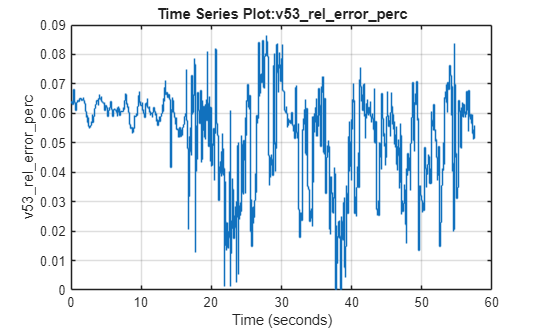

figure(2),plot(out.logsout{1}.Values),grid

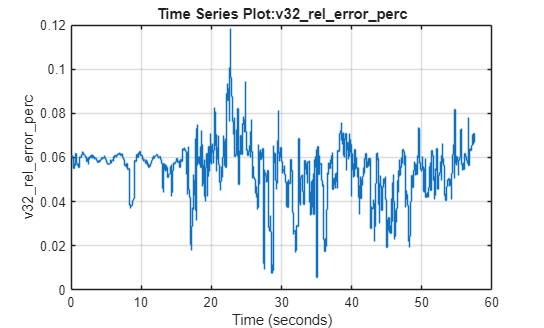

figure(3),plot(out.logsout{2}.Values),grid

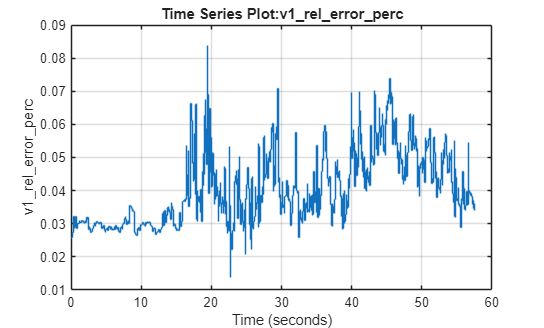

figure(4),plot(out.logsout{3}.Values),grid

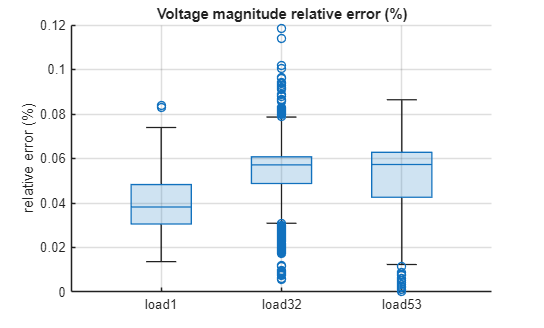


figure(5),boxchart([out.logsout{3}.Values.Data out.logsout{2}.Values.Data out.logsout{1}.Values.Data]),grid
ha = gca;
ha.XTickLabel = {'load1','load32','load53'};
ylabel('relative error (%)')
title('Voltage magnitude relative error (%)')